# WindSimfaster with NORA3: case of Sørlige Nordsjø II (North Sea)

This tutorial relies on NORA3 hindcast data to provide mean wind speed  data at Sørlige Nordsjø II in the North Sea, from which friction  velocity and turbulence intensities are derived. These inputs are then  used with WindSimFaster to generate a spatially correlated wind field  with a non-analytical mean wind speed profile. Note that non-neutral  atmospheres are not explicitly modeled here, but are implicitly  accounted for in the mean wind speed profile. For a more realistic  setup, the shape of the one-point velocity spectrum, the co-coherence of turbulence, and the friction velocity should also be  stability-dependent.

##  Time and frequency definitions

clearvars;close all;clc;
addpath ./functions
fs = 6; % sampling frequency (in Hertz)
M = 13; % M is the power of 2: If M = 10, 2^M = 1024 time step
[t,f] = getSamplingPara(M,fs);

Duration of target time series is 0.379 hours, i.e. 1.37e+03 sec 



N=numel(t); % number of time step (should be equal to 2^M)
Nfreq = numel(f); % number of frequency step (should be equal to 2^(M-1))
dt = median(diff(t)); % time step (should be equal to 1/fs)

##  Grid definition

Nyy = 15; % number of nodes along the y axis
Nzz = 15; % number of nodes along the z axis
ymin = -120;
ymax = 120;
zmin= 10;
zmax = zmin +270;
y = linspace(ymin,ymax,Nyy);
z = linspace(zmin,zmax,Nzz);
[Y,Z] = meshgrid(y,z);
M = numel(Z(:));

##  Mean wind speed profile from NORA3 for Sørlige Nordsjø II

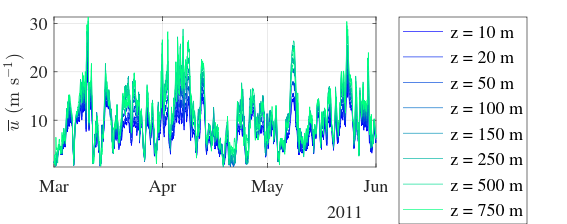

%  We download data from https://zenodo.org/records/10048159
if ~exist('spatialAvgData_SN2.nc','file')
    error('The dataset is not found. You can download it at https://zenodo.org/records/10048159');
end
meanU_NORA3 = ncread("spatialAvgData_SN2.nc",'U_median');
z_NORA3 = ncread("spatialAvgData_SN2.nc",'z');
time = datetime(1970,1,1) + hours(ncread("spatialAvgData_SN2.nc",'time'));

meanU_NORA3(meanU_NORA3>100) = nan;
myColor = winter(numel(z_NORA3));
clear leg

clf;close all
figure('position',[500 200 1139         450])
p=plot(time,meanU_NORA3);
for ii=1:numel(z_NORA3), p(ii).Color = myColor(ii,:); end
for ii=1:numel(z_NORA3), leg{ii} = sprintf(' z = %2.0f m',z_NORA3(ii)); end
legend(leg{:},'location','eastoutside')
ylabel('$\overline{u}$ (m s$^{-1}$)','interpreter','latex')
set(gcf, 'color', 'w'); % Set figure background color
set(findall(gcf, '-property',...
    'FontSize'), 'FontSize', 14, 'FontName', 'Times'); % Set font properties
grid on; % Enable grid for readability
axis tight; % Tighten axis limits
xlim([datetime(2011,3,1),datetime(2011,6,1)])

##  Interpolate the mean wind speed profile on the grid

% The case of a single even it taken, e.g.  15-03-2011 at 01:00
[~,indTime]=min(abs(time-datetime(2011,03,11,01,0,0)));

meanU = interp1(z_NORA3,meanU_NORA3(indTime,:),Z,'makima');

##  Friction velocity defined based on the turbulence intensity


zHub = 150; % we assume a wind turbine at SN2 with a hub height of 150 m
[~,indZhub] = min(abs(z_NORA3-150));
Iu_linear = 0.087.*(1+0.302.*(meanU_NORA3(indTime,indZhub)/10-1))./(zHub/10).^(0.2); % Linear model from Andersen and Løvseth (2006)
stdU = Iu_linear.*meanU_NORA3(indTime,indZhub); % standard deviation of the along-wind component at 150 m
u_star = stdU/2.3; % See Cheynet et al (2018) Fig 5
fprintf('The date of the selected event is %s\n',datestr(time(indTime)));

The date of the selected event is 11-Mar-2011 01:00:00


fprintf('The hub height is %2.0f m\n',z_NORA3(indZhub))

The hub height is 150 m


fprintf('The Turbulence intensity for the along-wind component is %2.2f \n',Iu_linear)

The Turbulence intensity for the along-wind component is 0.05 


fprintf('The mean wind speed is %2.1f m/s \n',meanU_NORA3(indTime,indZhub))

The mean wind speed is 9.6 m/s 


fprintf('The friction velocity at hub height is %2.1f m/s \n\n',u_star)

The friction velocity at hub height is 0.2 m/s 



##  Generate uncorrelated wind velocity histories

tic
Nf = numel(f);
u = zeros(N,M);
v = zeros(N,M);
w = zeros(N,M);
Su = zeros(Nf,M);
Sv = zeros(Nf,M);
Sw = zeros(Nf,M);
dummyU = meanU(:);
dummyZ = Z(:);

rng(1) % for reprodcuibility only!
for ii=1:M
    [Su(:,ii),Sv(:,ii),Sw(:,ii)] = KaimalModel(dummyU(ii),dummyZ(ii),f,u_star);
    [u(:,ii),t] = randomProcess(f,Su(:,ii));
    [v(:,ii),~] = randomProcess(f,Sv(:,ii));
    [w(:,ii),~] = randomProcess(f,Sw(:,ii));
end
toc

Elapsed time is 0.358156 seconds.


##  Introduce a spatial correlation in the wind field with the coherence

Cuy = 10; % Davenport coherence coefficient for lateral separations and u component
Cuz = 12; % Davenport coherence coefficient for vertical separations and u component

Cvy = 10; % Davenport coherence coefficient for lateral separations and v component
Cvz = 12; % Davenport coherence coefficient for vertical separations and v component

Cwy = 5; % Davenport coherence coefficient for lateral separations and w component
Cwz = 6; % Davenport coherence coefficient for vertical separations and w component

[u_corr] = windSimFaster(Y,Z,meanU,Cuy,Cuz,f,u);

Elapsed time is 14.837873 seconds.


[v_corr] = windSimFaster(Y,Z,meanU,Cvy,Cvz,f,v);

Elapsed time is 17.249525 seconds.


[w_corr] = windSimFaster(Y,Z,meanU,Cwy,Cwz,f,w);

Elapsed time is 11.012491 seconds.


% reshape
u_corr = reshape(u_corr,[N,Nzz,Nyy]);
v_corr = reshape(v_corr,[N,Nzz,Nyy]);
w_corr = reshape(w_corr,[N,Nzz,Nyy]);
% Add the mean wind speed (only for the u-component)
u_corr = u_corr + reshape(meanU, [1, size(meanU)]);

##  Time series visualization

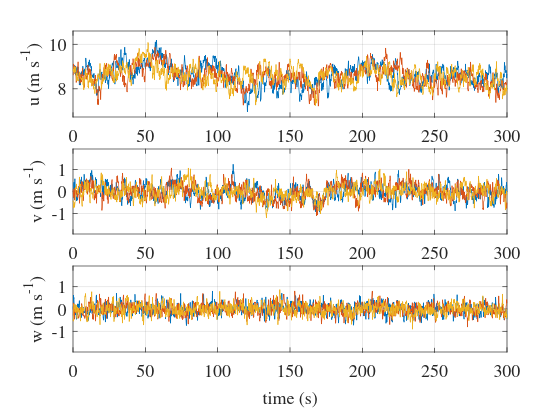

[~, indEnd] = min(abs(t-300));
clf;close all;
figure
tiledlayout(3,1,'TileSpacing','tight')

stdRef4 = 4.*std(u_corr(:));
nexttile
plot(t(1:indEnd),squeeze(u_corr(1:indEnd,1,1:2:6)))
ylabel('u (m s^{-1})')
grid on; 
xlim([0 300])
ylim([-stdRef4 stdRef4]+min(meanU(:)))

nexttile
plot(t(1:indEnd),squeeze(v_corr(1:indEnd,1,1:2:6)))
ylabel('v (m s^{-1})')
grid on; 
xlim([0 300])
ylim([-stdRef4 stdRef4])

nexttile
plot(t(1:indEnd),squeeze(w_corr(1:indEnd,1,1:2:6)))
ylabel('w (m s^{-1})')
xlabel('time (s)')
grid on; 
xlim([0 300])
ylim([-stdRef4 stdRef4])

set(gcf, 'color', 'w'); % Set figure background color
set(findall(gcf, '-property',...
    'FontSize'), 'FontSize', 14, 'FontName', 'Times'); % Set font properties

##  Mean wind speed profile

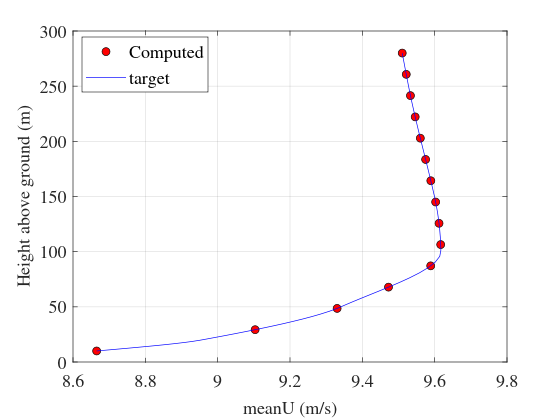

figure
plot(squeeze(mean(u_corr(:,:,1))),z,'ko','markerfacecolor','r')
hold on
z1 = logspace(log10(z(1)),log10(z(end)),60);
dummyU = interp1(z_NORA3,meanU_NORA3(indTime,:),z1,'makima');
plot(dummyU,z1,'b')
legend('Computed','target','location','best')
xlabel('meanU (m/s)')
ylabel('Height above ground (m)')
set(gcf, 'color', 'w'); % Set figure background color
set(findall(gcf, '-property',...
    'FontSize'), 'FontSize', 14, 'FontName', 'Times'); % Set font properties
grid on; % Enable grid for readability

% axis tight; % Tighten axis limits

##  Pseudocolorplot

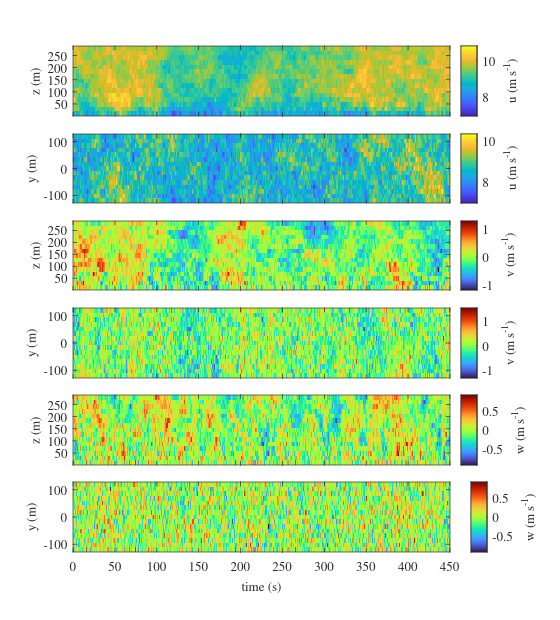

[~, indEnd] = min(abs(t-450));
figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1), pos(2), pos(3), pos(4) + 200]);
tiledlayout(6,1,"TileSpacing","loose")
nexttile
imagesc(t(1:indEnd),z,squeeze(u_corr(1:indEnd,:,1))');axis xy
ylabel('z (m)')
% xlabel('time (s)')
c = colorbar;colormap(gca,'parula')
ylabel(c,'u (m s^{-1})')
set(gca,'xticklabel',[])
nexttile
imagesc(t(1:indEnd),y,squeeze(u_corr(1:indEnd,1,:))');axis xy
ylabel('y (m)')
c = colorbar;colormap(gca,'parula')
ylabel(c,'u (m s^{-1})')
set(gca,'xticklabel',[])

nexttile
imagesc(t(1:indEnd),z,squeeze(v_corr(1:indEnd,:,1))');axis xy
ylabel('z (m)')
% xlabel('time (s)')
c = colorbar;colormap(gca,'turbo')
ylabel(c,'v (m s^{-1})')
set(gca,'xticklabel',[])
nexttile
imagesc(t(1:indEnd),y,squeeze(v_corr(1:indEnd,1,:))');axis xy
ylabel('y (m)')
c = colorbar;colormap(gca,'turbo')
ylabel(c,'v (m s^{-1})')
set(gca,'xticklabel',[])
nexttile
imagesc(t(1:indEnd),z,squeeze(w_corr(1:indEnd,:,1))');axis xy
ylabel('z (m)')
% xlabel('time (s)')
c = colorbar;colormap(gca,'turbo')
ylabel(c,'w (m s^{-1})')
set(gca,'xticklabel',[])
set(gca,'xticklabel',[])

nexttile
imagesc(t(1:indEnd),y,squeeze(w_corr(1:indEnd,1,:))');axis xy
ylabel('y (m)')
xlabel('time (s)')
c = colorbar;colormap(gca,'turbo')
ylabel(c,'w (m s^{-1})')



set(gcf,'color','w')
set(findall(gcf, '-property',...
    'FontSize'), 'FontSize', 10, 'FontName', 'Times'); % Set font properties
axis tight; % Tighten axis limits

##  Power spectral density

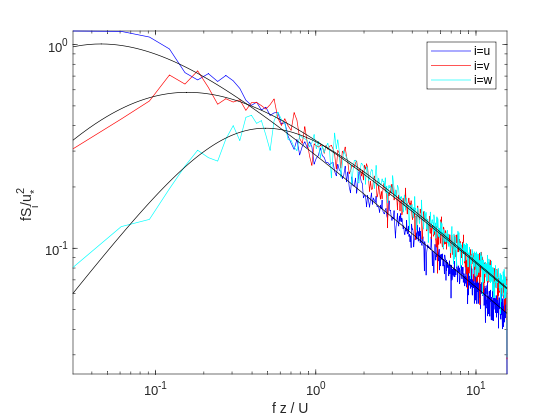

u = reshape(u,[N,Nzz,Nyy]);
[~,indZ]=min(abs(Z(:,1)-50));
Nf = round(N/8); % numbe of points for each segments (50% overlapping)
[Su0,f0]=pwelch(detrend(squeeze(u_corr(:,indZ,1))),Nf,round(Nf/2),Nf,fs);
[Sv0,f0]=pwelch(detrend(squeeze(v_corr(:,indZ,1))),Nf,round(Nf/2),Nf,fs);
[Sw0,f0]=pwelch(detrend(squeeze(w_corr(:,indZ,1))),Nf,round(Nf/2),Nf,fs);
Su0 = f0.*Su0./u_star.^2;
Sv0 = f0.*Sv0./u_star.^2;
Sw0 = f0.*Sw0./u_star.^2;

clear p
fr0 = Z(indZ,1)./meanU(indZ,1).*f0;
fr = Z(indZ,1)./meanU(indZ,1).*f;
coeff = f(:)./u_star.^2;
figure
p(1)=loglog(fr0,Su0,'b');
hold on; box on;
p(2)=loglog(fr0,Sv0,'r');
p(3)=loglog(fr0,Sw0,'c');

loglog(fr,coeff.*Su(:,indZ),'k')
loglog(fr,coeff.*Sv(:,indZ),'k')
loglog(fr,coeff.*Sw(:,indZ),'k')
xlabel('f z / U')
ylabel('fS_i/u^2_* ')
legend(p,'i=u','i=v','i=w')
axis tight
set(gcf,'color','w')
xlim([fr0(2),fr0(end)])

##  Coherence along the y direction

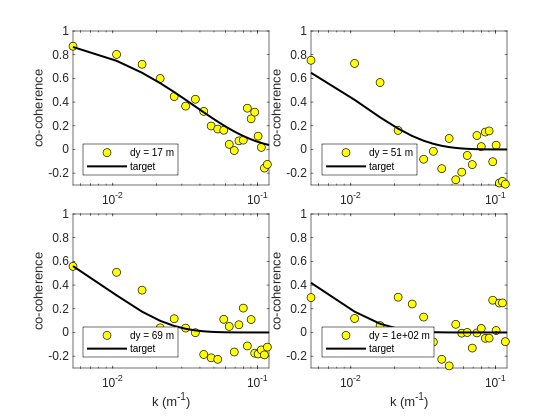


Nblock = 10; % a lot of block here to make it easier to visualize
Ncoh = round(N/Nblock);

distTarget = [25,50,75,100];
dy = abs(Y(1,:)'-Y(1,:)); % Matrix distance along y
dz = abs(Z(1,:)'-Z(1,:)); % Matrix distance along z
uCoh = 0.5*(meanU(1,:)'+meanU(1,:)); % Mean wind velocity between each nodes
% lateral separation
ay = Cuy.*dy;
% vertical separation
az = Cuz.*dz;
% Combine them into the coherence matrix for lateral and vertical
% separations
K = -sqrt(ay.^2+az.^2)./uCoh;
% Anonymous function
cohDavenport = @(K,f) exp(K.*f);

Ntarget = numel(distTarget);

figure
tiledlayout(2,2,"TileSpacing","tight")
for ii=1:Ntarget
    [~,indDist] = min(abs(dy(1,:)-distTarget(ii)));
    [cocoh,~,freq] = coherence(u_corr(:,1,1),u_corr(:,1,indDist),Ncoh,round(Ncoh/2),Ncoh,fs);
    k = 2*pi*freq./uCoh(1,indDist);
    nexttile
    semilogx(k,cocoh,'ko','markerfacecolor','y');
    box on;hold on
    plot(k,cohDavenport(K(1,indDist),freq),'k','linewidth',1.5);
    legend(['dy = ',num2str(dy(1,indDist),2),' m'],'target','location','southwest');
    xlim([0,0.12])
    ylim([-0.3,1])
    ylabel('co-coherence')
    if ii>2,        xlabel('k (m^{-1})');    end
    set(gcf,'color','w')
end

##  Coherence along the z direction

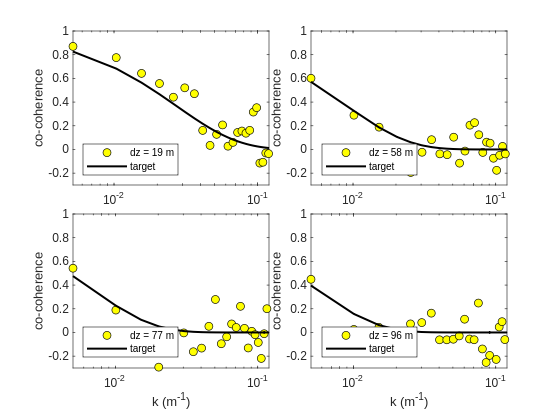


Nblock = 10; % a lot of block here to make it easier to visualize
Ncoh = round(N/Nblock);

distTarget = [25,50,75,100];
dy = abs(Y(:,1)'-Y(:,1)); % Matrix distance along y
dz = abs(Z(:,1)'-Z(:,1)); % Matrix distance along z
uCoh = 0.5*(meanU(:,1)'+meanU(:,1)); % Mean wind velocity between each nodes
% lateral separation
ay = Cuy.*dy;
% vertical separation
az = Cuz.*dz;
% Combine them into the coherence matrix for lateral and vertical
% separations
K = -sqrt(ay.^2+az.^2)./uCoh;
% Anonymous function
cohDavenport = @(K,f) exp(K.*f);

Ntarget = numel(distTarget);

figure
tiledlayout(2,2,"TileSpacing","tight")
for ii=1:Ntarget
    [~,indDist] = min(abs(dz(1,:)-distTarget(ii)));
    [cocoh,~,freq] = coherence(u_corr(:,1,1),u_corr(:,indDist,1),Ncoh,round(Ncoh/2),Ncoh,fs);
    k = 2*pi*freq./uCoh(indDist,1);
    nexttile
    semilogx(k,cocoh,'ko','markerfacecolor','y');
    box on;hold on
    plot(k,cohDavenport(K(indDist,1),freq),'k','linewidth',1.5);
    legend(['dz = ',num2str(dz(indDist,1),2),' m'],'target','location','southwest');
    xlim([0,0.12])
    ylim([-0.3,1])
    ylabel('co-coherence')
    if ii>2,        xlabel('k (m^{-1})');    end
    set(gcf,'color','w')
end

## Saving data into a bts file

zHub = 150;
ntower = 0;
fname = 'testFile.bts';
z1 = Z(:,1);
z = Z(:,1);
y = Y(1,:)';

if z(1)>z(end),
    z = flipud(z);
    u_corr = flip(u_corr,2);
    v_corr = flip(v_corr,2); 
    w_corr = flip(w_corr,2); 
end
uHub = interp1(z1,meanU(:,1),zHub,'linear');
write2bts(fname,u_corr,v_corr,w_corr,t,y,z,zHub,uHub,ntower);

Reading from the file testFile.bts with heading: 
   "This full-field file was generated by windSimFaster".
